% Speeds
omega_1 = 500;
omega_2 = omega_1;
omega_3 = omega_1;
omega_4 = omega_1;

% Phhysical Constants
g = 9.81;

% Drone Constants
m = 1.7;
l = 0.23;

k = 9.8e-6;
b = 1.6e-7;
k_thrust = 9.8e-6;

Inertial_body_radius = 0.2;
Inertial_body_height = 0.05;
Ixx = m * (3 * Inertial_body_radius^2 + Inertial_body_height^2) / 12;
Iyy = m * (3 * Inertial_body_radius^2 + Inertial_body_height^2) / 12;
Izz = (m * Inertial_body_radius^2)/2;
I = diag([Ixx, Iyy, Izz]);

% Simulation Time
start_time = 0;
end_time = 1000;
dt = 0.05;
times = start_time:dt:end_time;
plot_data = [];

N = numel(times);

% Initial Conditions
x_t = [0; 0; 0];
x_t_1 = x_t;
x_t_dot = zeros(3, 1);
theta_t = zeros(3, 1);
theta_t_1 = theta_t;
theta_t_dot = zeros(3,1);

% Initial Speed
speeds = [1000, 1000, 1000, 1000];

% For plotting
pos = zeros([3 length(times)]);
ang = zeros([3 length(times)]);

% Simulation
count = 1;
tic
for t = times

% Transform from world to robot coordinates
pqr = theta_t_dot_2_pqr(theta_t_dot, theta_t);

% Dynamics
a = linear_dynamics(speeds, theta_t, g, k_thrust, m);
pqr_dot = angular_dynamics(speeds, pqr, I, l, b, k);

% Update
pqr = pqr + dt * pqr_dot;
theta_t_dot = pqr_2_theta_t_dot(pqr, theta_t);
theta_t = theta_t + dt * theta_t_dot;

x_t_dot = x_t_dot + dt * a;
x_t = x_t + dt * x_t_dot;

% % Controller
speeds = Controller(speeds, x_t, x_t_dot, theta_t, theta_t_dot, x_t_1, theta_t_1);

% Memory
x_t_1 = x_t;
theta_t_1 = theta_t;

% Plotting
pos(:, count) = x_t;
ang(:, count) = theta_t;
count = count + 1;

end
toc

Elapsed time is 0.088385 seconds.


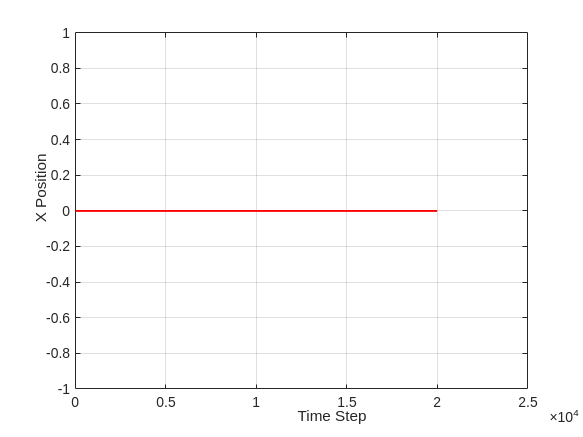


% Extract position and angles
x = pos(1, :);
y = pos(2, :);
z = pos(3, :);

roll = ang(1, :);
pitch = ang(2, :);
yaw = ang(3, :);

% Plot X Position
figure;
plot(x, 'r', 'LineWidth', 1.5);
xlabel('Time Step');
ylabel('X Position');
title('X Position vs Time');
grid on;

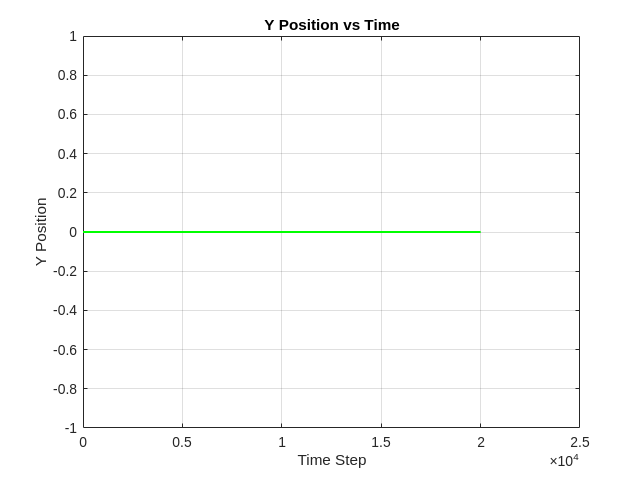


% Plot Y Position
figure;
plot(y, 'g', 'LineWidth', 1.5);
xlabel('Time Step');
ylabel('Y Position');
title('Y Position vs Time');
grid on;

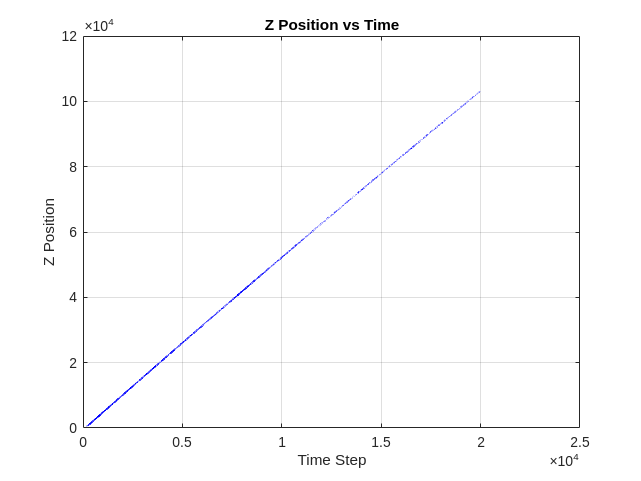


% Plot Z Position
figure;
plot(z, 'b', 'LineWidth', 1.5);
xlabel('Time Step');
ylabel('Z Position');
title('Z Position vs Time');
grid on;

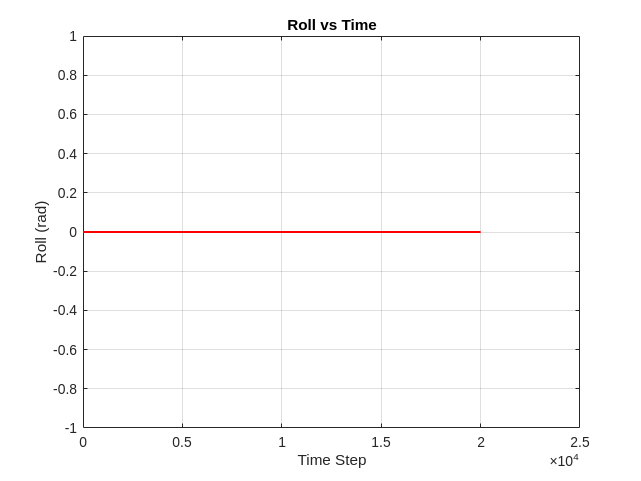


% Plot Roll
figure;
plot(roll, 'r', 'LineWidth', 1.5);
xlabel('Time Step');
ylabel('Roll (rad)');
title('Roll vs Time');
grid on;

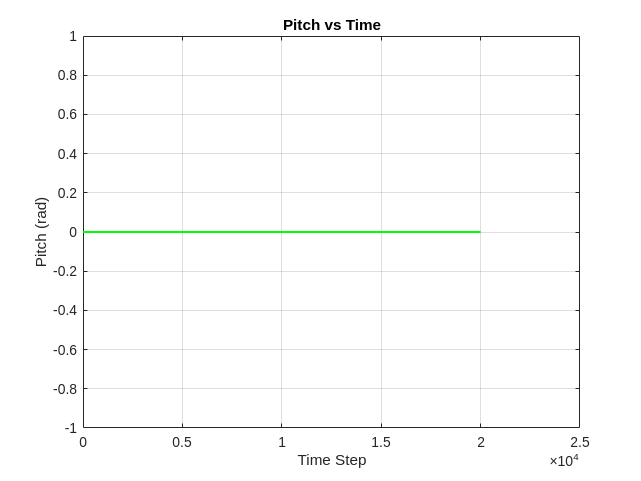


% Plot Pitch
figure;
plot(pitch, 'g', 'LineWidth', 1.5);
xlabel('Time Step');
ylabel('Pitch (rad)');
title('Pitch vs Time');
grid on;

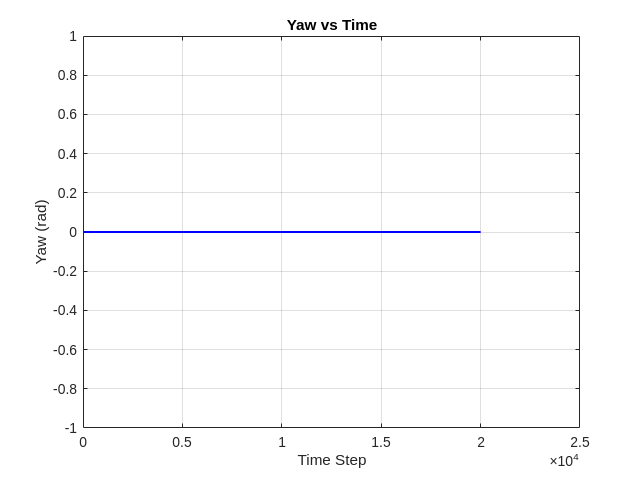


% Plot Yaw
figure;
plot(yaw, 'b', 'LineWidth', 1.5);
xlabel('Time Step');
ylabel('Yaw (rad)');
title('Yaw vs Time');
grid on;


function pqr = theta_t_dot_2_pqr(theta_t_dot, theta_t)
phi = theta_t(1);
theta = theta_t(2);
psi = theta_t(3);
pqr = [1 0 -sin(theta);
0 cos(phi) cos(theta)*sin(phi);
0 -sin(phi) cos(theta)*cos(phi)] * theta_t_dot;
end

function a = linear_dynamics(speeds, theta_t, g, k_thrust, m)
gravity = [0; 0; -g];

R = Rot_matrix(theta_t);
T = R * thrust(speeds, k_thrust);
% Fd = -kd * xdot;

a = gravity + 1 / m * T; % + Fd;
end

function R = Rot_matrix(theta_t)
phi = theta_t(1);
theta = theta_t(2);
psi = theta_t(3);
R = [ cos(psi)*cos(theta), cos(psi)*sin(theta)*sin(phi)-sin(psi)*cos(phi), cos(psi)*sin(theta)*cos(phi)+sin(psi)*sin(phi);
sin(psi)*cos(theta), sin(psi)*sin(theta)*sin(phi)+cos(psi)*cos(phi), sin(psi)*sin(theta)*cos(phi)-cos(psi)*sin(phi);
-sin(theta), cos(theta)*sin(phi), cos(theta)*cos(phi)
];
end

function T = thrust(speeds, k_thrust)
T = [0; 0; k_thrust * sum(speeds.^2)];
end

function pqr_dot = angular_dynamics(speeds, pqr, I, l, b, k)
tau = torques(speeds, l, b, k);
pqr_dot = inv(I) * (tau - cross(pqr, I * pqr));
end
      
function tau = torques(speeds, l, b, k)
speeds = speeds.^2;
tau = [
l * k * (speeds(1) - speeds(3))
l * k * (speeds(2) - speeds(4))
b * (speeds(1) - speeds(2) + speeds(3) - speeds(4))];
end

function theta_t_dot = pqr_2_theta_t_dot(pqr, theta_t)
phi = theta_t(1);
theta = theta_t(2);
psi = theta_t(3);
theta_t_dot = inv([1 0 -sin(theta);
0 cos(phi) cos(theta)*sin(phi);
0 -sin(phi) cos(theta)*cos(phi)]) * pqr;
end

function speeds = Controller(speeds, x_t, x_t_dot, theta_t, theta_t_dot, x_t_1, theta_t_1)
% To be made
if speeds(1) == 652
speeds = [652, 652, 652, 652];
else
speeds = [speeds(1)-1 speeds(1)-1 speeds(1)-1 speeds(1)-1];
end
end
